# Beispiel Strömungsfeld

clear

## Plot für t = 0, t = 5 und t = 10

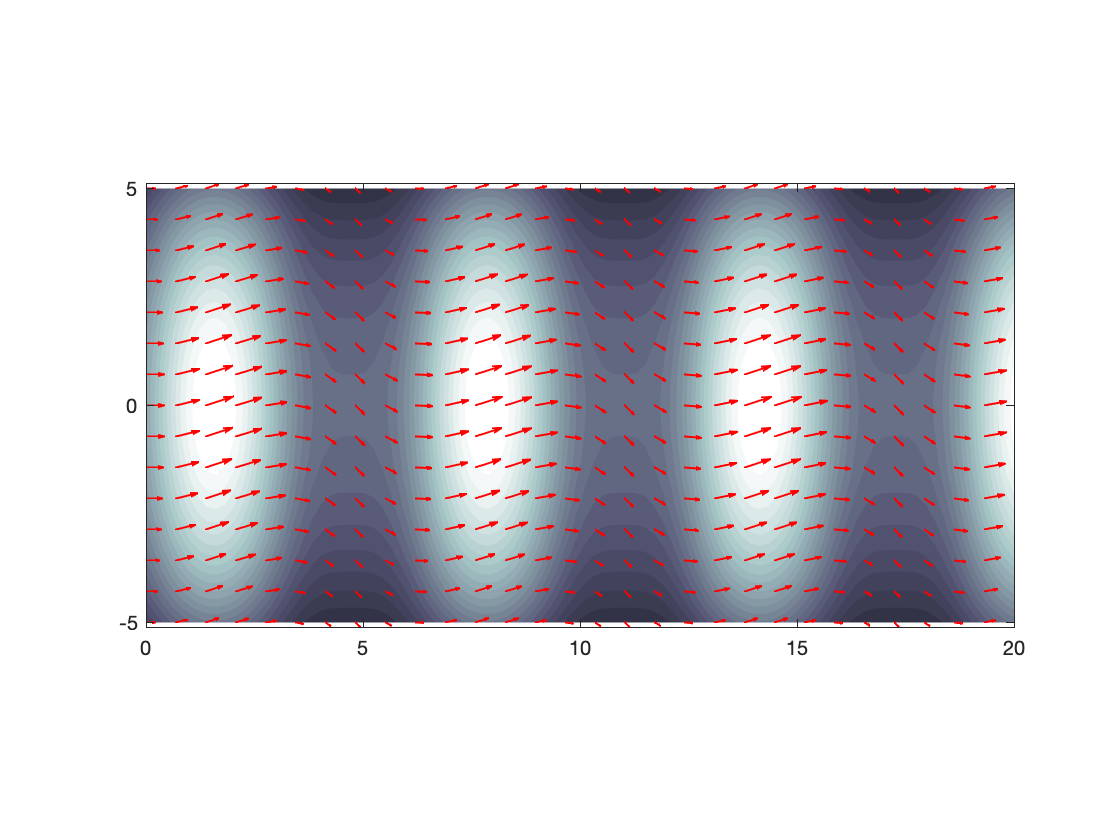

plotit(0)

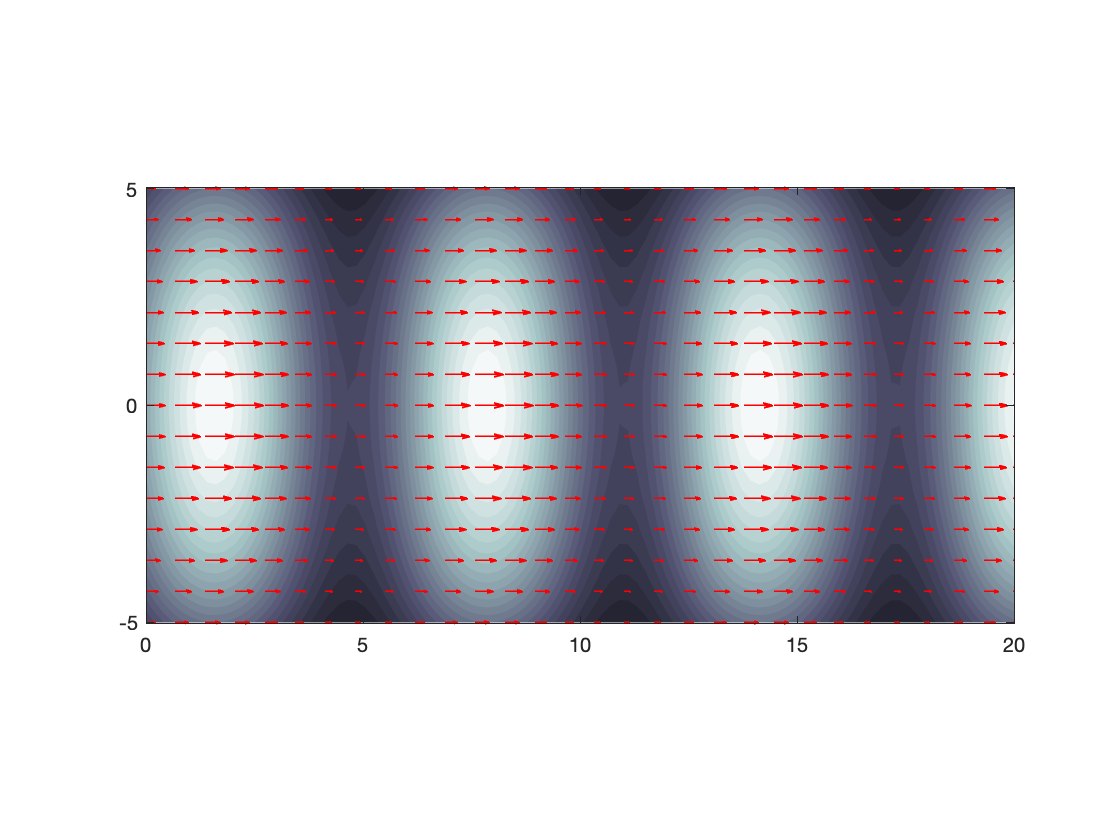

plotit(5)

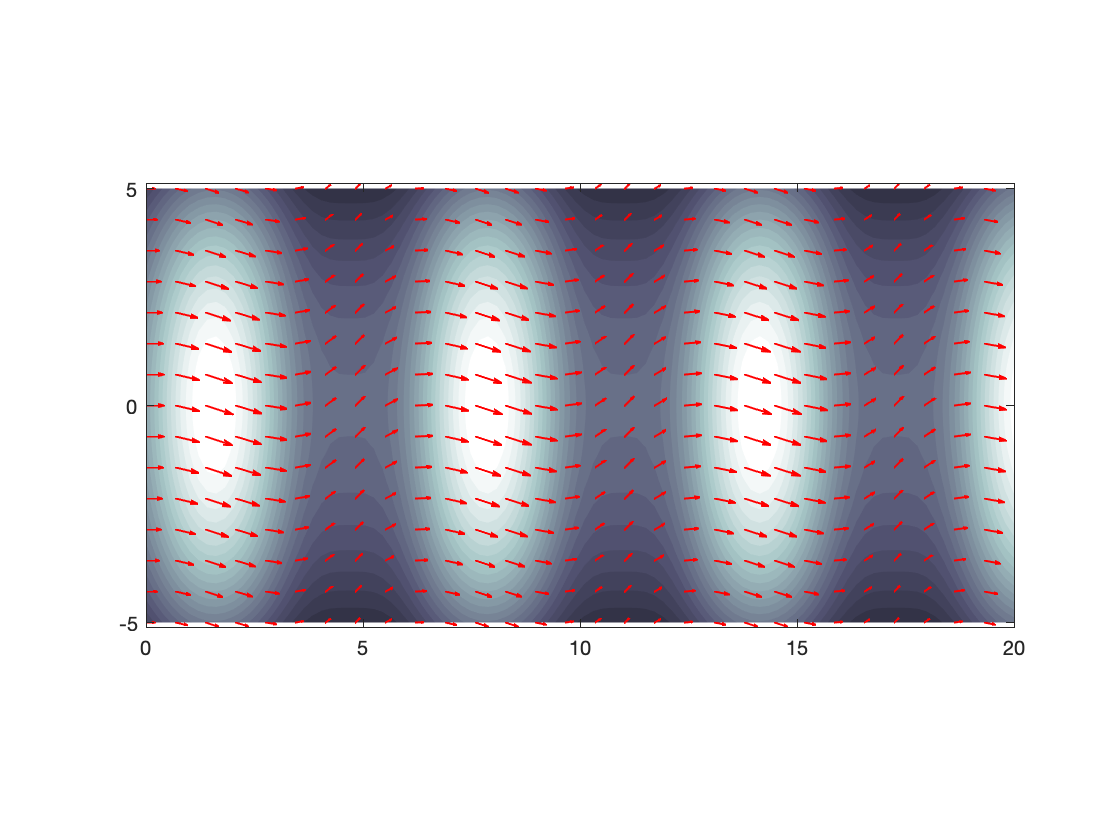

plotit(10)

## Sechs Zeitschritte von Hand

Funktion des Strömungsfeldes

v = @(x, t) (50 - x(2)^2) / 50 * [
    (2 + sin(x(1)))
    cos(0.1 * pi * t) * sin(x(1))
];

Rechenschritte

x0 = [0; 0];
v0 = v(x0, 0);
x1 = x0 + 2 * v0;
v1 = v(x1, 2);
x2 = x1 + 2 * v1;
v2 = v(x2, 4);
x3 = x2 + 2 * v2;
v3 = v(x3, 6);
x4 = x3 + 2 * v3;
v4 = v(x4, 8);
x5 = x4 + 2 * v4;
v5 = v(x5, 10);
x6 = x5 + 2 * v5;

Plot

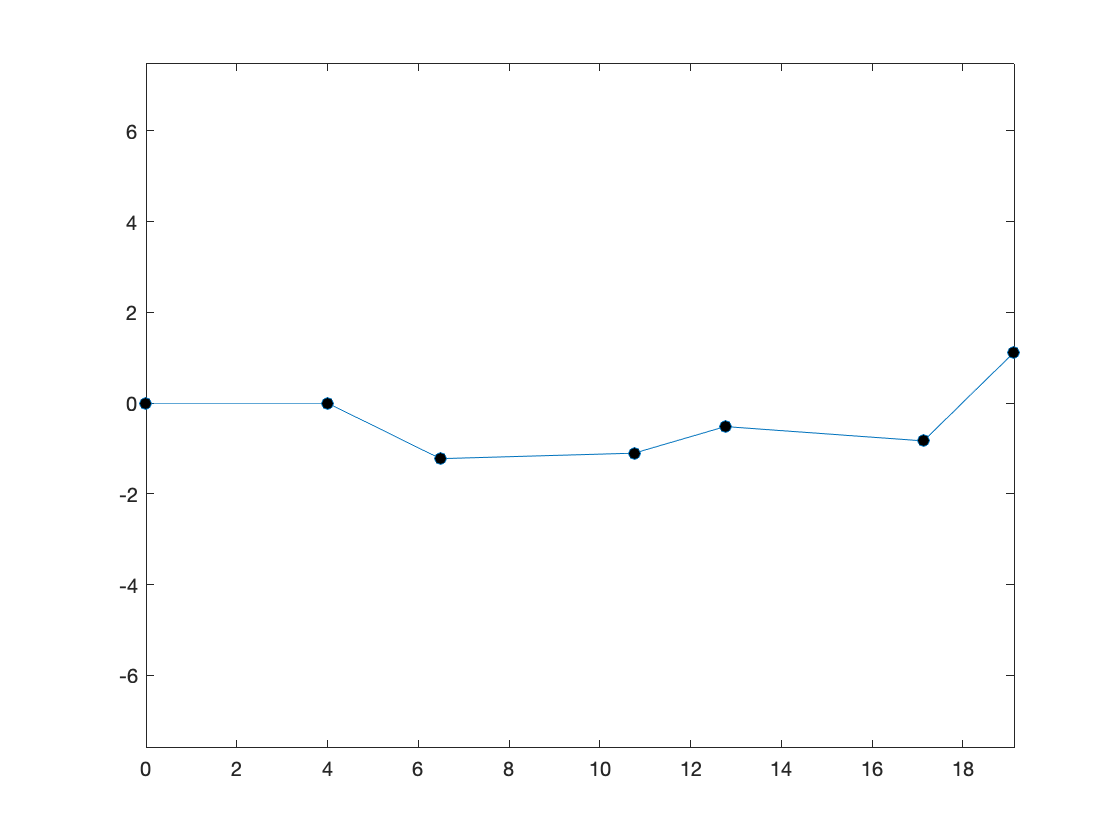

x = [x0,x1, x2, x3, x4, x5, x6];
plot(x(1, :), x(2, :), '-o', 'MarkerFaceColor', 'k')
axis equal

## Lösung für viele Startpunkte

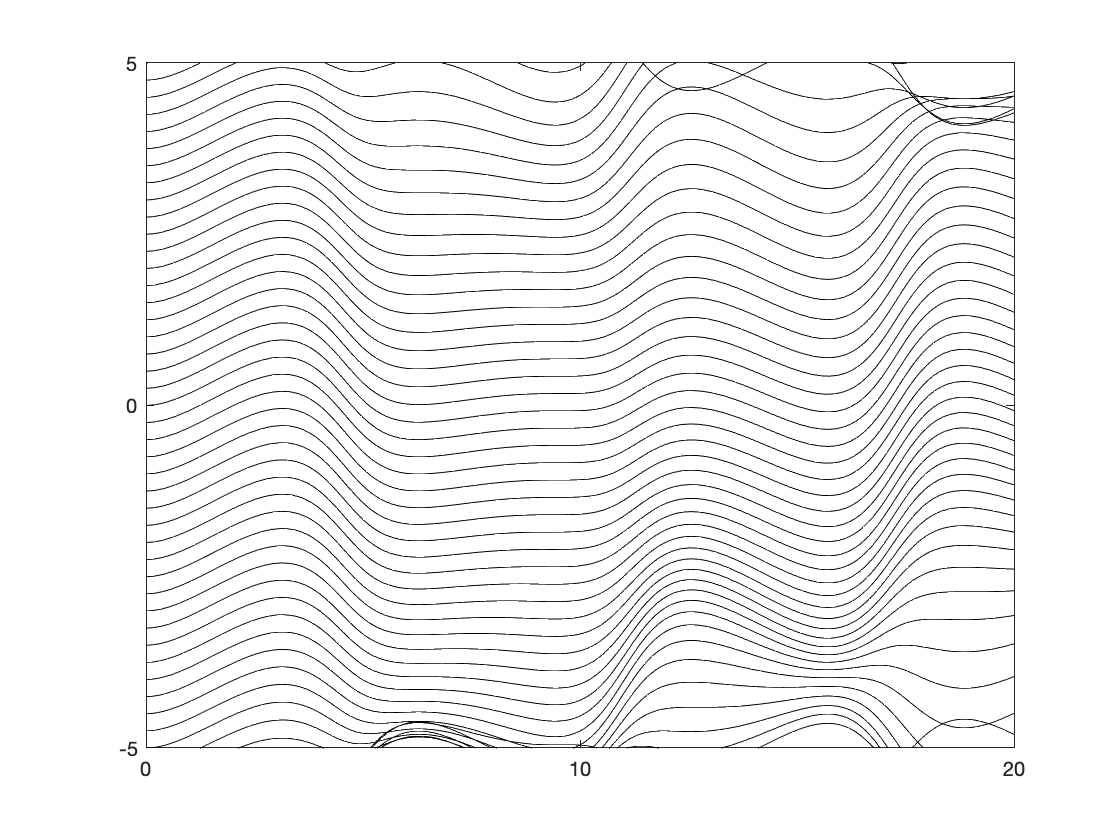

F = @(t, x) v(x, t);

for x2 = -7:0.25:7

    [t, x] = odesolve(F, [0, 60], 0.1, [0; x2], 'Runge Kutta');

    plot(x(:, 1), x(:, 2), 'k')
    hold on
end
hold off

xlim([0, 20])
ylim([-5, 5])
xticks(0:10:20)
yticks(-5:5:5)
saveas(gcf, '../flowfield-all.png')

## Funktion zum Plotten des Strömungsfeldes zum Zeitpunkt t

function plotit(t)

Funktion des Strömungsfeldes

    s = @(y) (50 - y.^2) / 50;
    vx = @(x, y, t)                      s(y) .* (2 + sin(x));
    vy = @(x, y, t) cos(0.1 * pi * t) .* s(y) .* sin(x);

Grobes Raster für Pfeile

    x1 = linspace(0, 20, 30);
    y1 = linspace(-5, 5, 15);
    [X1, Y1] = meshgrid(x1, y1);
    VX1 = vx(X1, Y1, t);
    VY1 = vy(X1, Y1, t);

Feines Raster für Farbdarstellung

    x2 = linspace(0, 20, 100);
    y2 = linspace(-5, 5, 50);
    [X2, Y2] = meshgrid(x2, y2);
    VX2 = vx(X2, Y2, t);
    VY2 = vy(X2, Y2, t);
    N2 = sqrt(VX2.^2 + VY2.^2);


Plot Farben für Strömungsgeschwindigkeit

    contourf(X2, Y2, N2, 0:0.1:3, 'LineColor', 'none');
    hold on

Strömungspfeile

    quiver(X1, Y1, VX1, VY1, 0.7, 'color', 'red', 'LineWidth', 1)
    hold off

Darstellung

    xlim([0, 20])
    xticks(0:5:20)
    ylim([-5, 5])
    caxis([0, 3])
    colormap bone
    axis equal

Sichern für Skript

    % saveas(gcf, sprintf('../flowfield-%i.png', t))
end